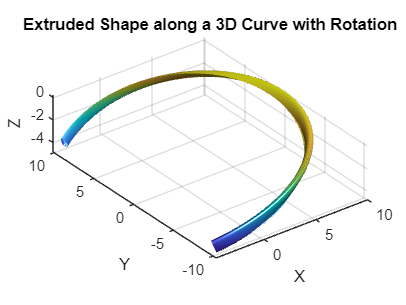

% Symbolic 3D extrusion of a 2D airfoil shape along a 3D curve using the Joukowsky transform

% Clear workspace
clear;
clc;

% Load symbolic library
syms t s

%% Define the 2D Shape
r = 1;
x_2D = t * heaviside(1 - t) + (t - 1) * heaviside(t - 1);

thickness = 0.5;

m = 0.02;
p = 0.4;

yt = 5 * thickness * (0.2969 * sqrt(t) - 0.1260 * t - 0.3516 * t^2 + 0.2843 * t^3 - 0.1036 * t^4);
yc = m / p^2 * (2 * p * t - t^2) * heaviside(p - t) + m / (1 - p)^2 * ((1 - 2*p) + 2*p*t - t^2) * heaviside(t - p);
yu = yt + yc;

% domain shift
yl_1 = yc - yt;
yl = subs(yl_1, t, (t-1));

% use dirac deltas to activate upper/lower
y_2D = yu * heaviside(1 - t) + yl * heaviside(t - 1);

%% Define the 3D Curve

% Parameters for the 3D curve (a helix in this case)
R = 10; % Radius of the helix
pitch = 2; % Vertical distance per revolution
n_turns = 3; % Number of turns

% Parametric equations for the 3D curve (helix)
x_curve = R * cos(s);
y_curve = R * sin(s);
z_curve = -1 * s ^ 2;

%% Define the Frenet-Serret Frame

% Derivatives to get tangent vector (T)
dx_ds = diff(x_curve, s);
dy_ds = diff(y_curve, s);
dz_ds = diff(z_curve, s);
T = [dx_ds, dy_ds, dz_ds];
T = T / norm(T);

% Derivative of tangent to get normal vector (N)
dT_ds = diff(T, s);
N = dT_ds / norm(dT_ds);

% Binormal vector (B) is the cross product of T and N
B = cross(T, N);

% Define the Rotation based on the distance along the curve

% Define the rotation angle as a function of s (linear relationship)
theta = s; % Rotation angle changes with distance along the curve

% 2D rotation matrix
R_matrix = [cos(theta), -sin(theta); sin(theta), cos(theta)];

% Apply the rotation to the 2D airfoil coordinates (x_2D, y_2D)
rotated_coords = R_matrix * [x_2D; y_2D];

x_2D_rot = rotated_coords(1);
y_2D_rot = rotated_coords(2);

%% Transform the 2D shape Along the Curve

% Define the parametric position along the curve
C = [x_curve, y_curve, z_curve];

% Express the final 3D coordinates of the airfoil after extrusion
X_final = C(1) + x_2D_rot * N(1) + y_2D_rot * B(1);
Y_final = C(2) + x_2D_rot * N(2) + y_2D_rot * B(2);
Z_final = C(3) + x_2D_rot * N(3) + y_2D_rot * B(3);

% Convert symbolic expressions to functions for numerical evaluation
X_func = matlabFunction(X_final, 'Vars', [s, t]);
Y_func = matlabFunction(Y_final, 'Vars', [s, t]);
Z_func = matlabFunction(Z_final, 'Vars', [s, t]);

%% Numerical Evaluation and Plotting

% Discretize the parameters
s_vals = linspace(-2, 2);  % Values for curve parameter (s)
t_vals = linspace(0, 2, 1000);  % Values for shape parameter (t)

% Evaluate the symbolic expressions numerically
[X_mesh, T_mesh] = meshgrid(s_vals, t_vals);
X_vals = X_func(X_mesh, T_mesh);
Y_vals = Y_func(X_mesh, T_mesh);
Z_vals = Z_func(X_mesh, T_mesh);

% Plot the extruded prop in 3D
figure;
surf(X_vals, Y_vals, Z_vals, 'EdgeColor', 'none');
axis equal;
xlabel('X');
ylabel('Y');
zlabel('Z');
title('Extruded Shape along a 3D Curve with Rotation');
camlight; lighting phong;